# Projection on polytopes

clc
clear all
close all
rng(0)

# Data

A = [1  1  1  0  0  0  0  0  0;
     0  0  0  1  1  1  0  0  0;
     0  0  0  0  0  0  1  1  1;
    -1  0  0 -1  0  0 -1  0  0;
     0 -1  0  0 -1  0  0 -1  0;
     0  0 -1  0  0 -1  0  0 -1];
pinvA = pinv(A);
m     = size(A, 2);
N     = null(A, 'rational');
pinvN = pinv(N);
Ax = 7000;
Ay = 5000;
[ix_max, iy_max, is_max, ~, ~, ~] = max_values(Ax, Ay)

ix_max = 200

iy_max = 280

is_max = 240


function [ie, iz, is, ixy, iB] = generate_data
    A = [1  1  1  0  0  0  0  0  0;
         0  0  0  1  1  1  0  0  0;
         0  0  0  0  0  0  1  1  1;
        -1  0  0 -1  0  0 -1  0  0;
         0 -1  0  0 -1  0  0 -1  0;
         0  0 -1  0  0 -1  0  0 -1];
    pinvA = pinv(A);
    N     = null(A, 'rational');
    Ax = 7000;
    Ay = 5000;
    [ix_max, iy_max, ~, ~, ~, ~] = max_values(Ax, Ay);

    ie = 300*(2*rand(4, 1)-1);
    iz = N*ie;
    gx = rand * 2*pi;
    ixa = ix_max * sin(gx);
    ixb = ix_max * sin(gx-2*pi/3);
    ixc = ix_max * sin(gx+2*pi/3);
    gy = rand * 2*pi;
    iya = iy_max * sin(gy);
    iyb = iy_max * sin(gy-2*pi/3);
    iyc = iy_max * sin(gy+2*pi/3);
    ixy = [ixa; ixb; ixc; iya; iyb; iyc];
    iB = pinvA * ixy;
    is = iB + iz;
end

[ie, iz, is, ixy, iB] = generate_data

ie =   188.8342
  243.4752
 -223.8079
  248.0255


iz =   456.5270
   34.9737
 -491.5007
 -432.3094
  188.8342
  243.4752
  -24.2176
 -223.8079
  248.0255


is =   353.5714
   78.6664
 -580.0449
 -422.4672
  345.3246
  267.7286
  -92.1638
 -145.1058
  194.4907


ixy =  -147.8071
  190.5860
  -42.7789
  161.0596
 -278.8852
  117.8255


iB =  -102.9556
   43.6927
  -88.5442
    9.8421
  156.4904
   24.2535
  -67.9462
   78.7021
  -53.5348



original = struct();
original.ie = ie;
original.iz = iz;
original.is = is;
original.ixy = ixy;

function compare(original, optimal_projection, projection, name)
    disp(strcat(['Comparation of projection method: ', name]))
    disp('  Original | Optimal | Actual')
    disp('ie')
    disp([original.ie, optimal_projection.ie, projection.ie]);
    % disp('iz')
    % disp([original.iz, optimal_projection.iz, projection.iz]);
    disp('is')
    disp([original.is, optimal_projection.is, projection.is]);
    disp('ixy')
    disp([original.ixy, optimal_projection.ixy, projection.ixy]);
end

# Constraints


$$-\check{i_s}\leq i_B+N\cdot i_\varepsilon\leq\hat{i_s}$$


Define matrices


$$A_c\cdot i_\varepsilon\leq b_c$$


Ac = [N; -N];
bc = [is_max - iB; is_max + iB];
pinvAc = pinv(Ac);

Polytope properties

analyzePolytope(Ac, bc);


=== Polytope Properties ===
Dimensión afín   : 4
Acotado          : Sí
Número de facetas: 15
Número de vértices: 46
Número de aristas : 277
Volumen/Área     : N/A para dimensión >3
Centroide        : [ -4.018 2.034 4.725 -1.398 ]
ChebyCenter      : [ -14.99 42.2 62.8 -30.04 ]
Inradius         : 98.5
Diámetro         : 893.8



Visualize slice

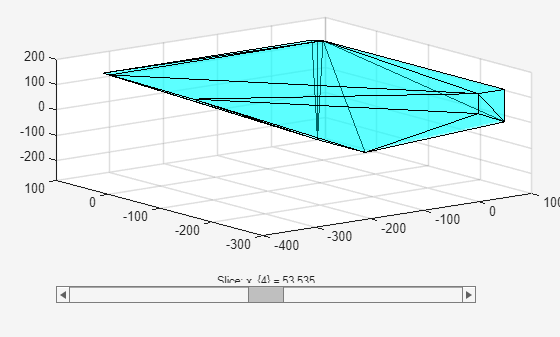

freeDim = 4;
visualizeSlice3D(Ac, bc, freeDim);

## Active set solver

H   = eye(4);
f   = -ie;
options = mpcActiveSetOptions;
[ie_proj, exitflag, iA, lambda] = mpcActiveSetSolver(H, f, Ac, bc, zeros(0, 4), zeros(0, 1), false(18, 1), options);
iz_proj = N * ie_proj;
is_proj = iB + iz_proj;
ixy_proj = A * is_proj;

exitflag

exitflag = int32
3


optimal_projection = struct();
optimal_projection.ie = ie_proj;
optimal_projection.iz = iz_proj;
optimal_projection.is = is_proj;
optimal_projection.ixy = ixy_proj;

% Max constraint violation original ie
max(Ac*ie - bc)

ans = 340.0449

% Max constraint violation projected ie
max(Ac*ie_proj - bc)

ans = 2.8422e-14

## Hardnet-aff

ie_correction = pinvAc * max(0, Ac * ie - bc);
ie_proj = ie - ie_correction;
iz_proj = N * ie_proj;
is_proj = iB + iz_proj;
ixy_proj = A * is_proj;

projection = struct();
projection.ie = ie_proj;
projection.iz = iz_proj;
projection.is = is_proj;
projection.ixy = ixy_proj;

compare(original, optimal_projection, projection, 'HardNet-Aff')

Comparation of projection method: HardNet-Aff
  Original | Optimal | Actual
ie
  188.8342   83.5096  160.8174
  243.4752   73.4527  184.6495
 -223.8079 -223.8079 -190.9267
  248.0255   78.0031  211.2999
is
  353.5714  -91.7981  262.8846
   78.6664  183.9910   73.8020
 -580.0449 -240.0000 -484.4937
 -422.4672 -147.1202 -335.6249
  345.3246  240.0000  317.3078
  267.7286   97.7062  208.9030
  -92.1638   77.8587  -88.3193
 -145.1058 -145.1058 -112.2246
  194.4907   24.4683  157.7651
ixy
 -147.8071 -147.8071 -147.8071
  190.5860  190.5860  190.5860
  -42.7789  -42.7789  -42.7789
  161.0596  161.0596  161.0596
 -278.8852 -278.8852 -278.8852
  117.8255  117.8255  117.8255



% Max constraint violation original ie
max(Ac*ie - bc)

ans = 340.0449

% Max constraint violation projected ie
max(Ac*ie_proj - bc)

ans = 244.4937

## Scalar clipping

Ac_ie = Ac * ie;
alpha_i = inf(size(Ac_ie));
pos = Ac_ie > 0;            
alpha_i(pos) = bc(pos) ./ Ac_ie(pos);
alpha = min(1, min(alpha_i));
ie_proj = alpha * ie;
iz_proj = N * ie_proj;
is_proj = iB + iz_proj;
ixy_proj = A * is_proj;

projection = struct();
projection.ie = ie_proj;
projection.iz = iz_proj;
projection.is = is_proj;
projection.ixy = ixy_proj;

compare(original, optimal_projection, projection, 'Scalar Clipping')

Comparation of projection method: Scalar Clipping
  Original | Optimal | Actual
ie
  188.8342   83.5096   58.1892
  243.4752   73.4527   75.0268
 -223.8079 -223.8079  -68.9663
  248.0255   78.0031   76.4290
is
  353.5714  -91.7981   37.7231
   78.6664  183.9910   54.4698
 -580.0449 -240.0000 -240.0000
 -422.4672 -147.1202 -123.3739
  345.3246  240.0000  214.6796
  267.7286   97.7062   99.2803
  -92.1638   77.8587  -75.4088
 -145.1058 -145.1058    9.7358
  194.4907   24.4683   22.8942
ixy
 -147.8071 -147.8071 -147.8071
  190.5860  190.5860  190.5860
  -42.7789  -42.7789  -42.7789
  161.0596  161.0596  161.0596
 -278.8852 -278.8852 -278.8852
  117.8255  117.8255  117.8255



% Max constraint violation original ie
max(Ac*ie - bc)

ans = 340.0449

% Max constraint violation projected ie
max(Ac*ie_proj - bc)

ans = 0

## Cimmino original

Mean of constraint violations

K      = 5;         % Number of iterations
lambda = 1.5;         % Relaxation factor
ie_proj = ie;       % Initialize projection
tic
n2 = sum(Ac.^2, 2); % Precalculate squared norm of each row of Ac
for k = 1:K
    R = Ac * ie_proj - bc;
    V = max(R, 0) ./ n2;
    d = (Ac.' * V) / size(Ac, 1);
    ie_proj = ie_proj - lambda * d;
end
toc

Elapsed time is 0.004243 seconds.


iz_proj = N * ie_proj;
is_proj = iB + iz_proj;
ixy_proj = A * is_proj;

projection = struct();
projection.ie = ie_proj;
projection.iz = iz_proj;
projection.is = is_proj;
projection.ixy = ixy_proj;

compare(original, optimal_projection, projection, 'Cimmino Mean')

Comparation of projection method: Cimmino Mean
  Original | Optimal | Actual
ie
  188.8342   83.5096  130.4157
  243.4752   73.4527  157.9109
 -223.8079 -223.8079 -227.2430
  248.0255   78.0031  188.1580
is
  353.5714  -91.7981  146.2860
   78.6664  183.9910  140.5200
 -580.0449 -240.0000 -434.6131
 -422.4672 -147.1202 -278.4844
  345.3246  240.0000  286.9061
  267.7286   97.7062  182.1644
  -92.1638   77.8587  -28.8612
 -145.1058 -145.1058 -148.5409
  194.4907   24.4683  134.6232
ixy
 -147.8071 -147.8071 -147.8071
  190.5860  190.5860  190.5860
  -42.7789  -42.7789  -42.7789
  161.0596  161.0596  161.0596
 -278.8852 -278.8852 -278.8852
  117.8255  117.8255  117.8255



% Max constraint violation original ie
max(Ac*ie - bc)

ans = 340.0449

% Max constraint violation projected ie
max(Ac*ie_proj - bc)

ans = 194.6131

## Cimmino modified

Max of constraint violations

K      = 5;         % Number of iterations
lambda = 1;         % Relaxation factor
ie_proj = ie;       % Initialize projection
tic
for k = 1:K
    R = Ac * ie_proj - bc;
    V = max(R, 0);
    [vmax, idx_max] = max(V);
    if vmax<=0
        break;
    end
    ai    = Ac(idx_max, :)';
    ri    = ai' * ie_proj - bc(idx_max);
    corr  = (ri / (ai' * ai)) * ai;
    ie_proj = ie_proj - lambda * corr;
end
toc

Elapsed time is 0.003172 seconds.


iz_proj = N * ie_proj;
is_proj = iB + iz_proj;
ixy_proj = A * is_proj;

projection = struct();
projection.ie = ie_proj;
projection.iz = iz_proj;
projection.is = is_proj;
projection.ixy = ixy_proj;

compare(original, optimal_projection, projection, 'Cimmino Max')

Comparation of projection method: Cimmino Max
  Original | Optimal | Actual
ie
  188.8342   83.5096   83.5096
  243.4752   73.4527   73.4527
 -223.8079 -223.8079 -223.8079
  248.0255   78.0031   78.0031
is
  353.5714  -91.7981  -91.7981
   78.6664  183.9910  183.9910
 -580.0449 -240.0000 -240.0000
 -422.4672 -147.1202 -147.1202
  345.3246  240.0000  240.0000
  267.7286   97.7062   97.7062
  -92.1638   77.8587   77.8587
 -145.1058 -145.1058 -145.1058
  194.4907   24.4683   24.4683
ixy
 -147.8071 -147.8071 -147.8071
  190.5860  190.5860  190.5860
  -42.7789  -42.7789  -42.7789
  161.0596  161.0596  161.0596
 -278.8852 -278.8852 -278.8852
  117.8255  117.8255  117.8255



% Max constraint violation original ie
max(Ac*ie - bc)

ans = 340.0449

% Max constraint violation projected ie
max(Ac*ie_proj - bc)

ans = 0

## Dykstra

K        = 1;         % Número de iteraciones externas
lambda   = 1;         % Factor de relajación (p.ej. 1.2)
ie_proj  = ie;        % Inicializa la proyección
n2       = sum(Ac.^2, 2);    % Precalcula ||a_i||^2 para cada restricción
p        = zeros(size(Ac));  % Correcciones acumuladas, una fila por restricción

tic
for k = 1:K
    % Recorremos cada semiespacio i=1..m
    for i = 1:size(Ac,1)
        ai  = Ac(i,:).';
        bi  = bc(i);
        aux = ie_proj + p(i,:).';
        ri  = ai.'*aux - bi;
        if ri > 0
            corr   = (ri/n2(i)) * ai;
            x_new  = aux - lambda * corr;
        else
            x_new  = aux;
        end
        p(i,:)    = (aux - x_new).';
        ie_proj   = x_new;
    end
end
toc

Elapsed time is 0.004731 seconds.



iz_proj   = N * ie_proj;
is_proj   = iB + iz_proj;
ixy_proj  = A * is_proj;

projection = struct();
projection.ie   = ie_proj;
projection.iz   = iz_proj;
projection.is   = is_proj;
projection.ixy  = ixy_proj;

compare(original, optimal_projection, projection, 'Dykstra')

Comparation of projection method: Dykstra
  Original | Optimal | Actual
ie
  188.8342   83.5096   83.5096
  243.4752   73.4527   73.4527
 -223.8079 -223.8079 -252.2008
  248.0255   78.0031   78.0031
is
  353.5714  -91.7981 -120.1910
   78.6664  183.9910  212.3838
 -580.0449 -240.0000 -240.0000
 -422.4672 -147.1202 -147.1202
  345.3246  240.0000  240.0000
  267.7286   97.7062   97.7062
  -92.1638   77.8587  106.2515
 -145.1058 -145.1058 -173.4987
  194.4907   24.4683   24.4683
ixy
 -147.8071 -147.8071 -147.8071
  190.5860  190.5860  190.5860
  -42.7789  -42.7789  -42.7789
  161.0596  161.0596  161.0596
 -278.8852 -278.8852 -278.8852
  117.8255  117.8255  117.8255



% Max constraint violation original ie
max(Ac*ie - bc)

ans = 340.0449

% Max constraint violation projected ie
max(Ac*ie_proj - bc)

ans = 2.8422e-14

## Douglas Peaceman Rachford

K = 2;
lambda = 1;               % relajación (normalmente 1)
x = ie;                   % estado
m = size(Ac,1);

tic
for k = 1:K
    x_old = x;
    % reflejar sucesivamente por cada semiespacio
    for i = 1:m
        ai = Ac(i,:).'; bi = bc(i);
        % proyección ortogonal a semiespacio i
        ri = ai.'*x - bi;
        if ri > 0
            p = x - (ri/(ai.'*ai)) * ai;
        else
            p = x;
        end
        % reflexión
        r = 2*p - x;
        % relajación
        x = x + lambda*(r - x);
    end
    % opcional: media con x_old para estabilidad DR
    x = 0.5*(x + x_old);
end
toc

Elapsed time is 0.004514 seconds.



ie_proj = x;
iz_proj   = N * ie_proj;
is_proj   = iB + iz_proj;
ixy_proj  = A * is_proj;

projection = struct();
projection.ie   = ie_proj;
projection.iz   = iz_proj;
projection.is   = is_proj;
projection.ixy  = ixy_proj;

compare(original, optimal_projection, projection, 'Douglas Peaceman Rachford')

Comparation of projection method: Douglas Peaceman Rachford
  Original | Optimal | Actual
ie
  188.8342   83.5096   83.5096
  243.4752   73.4527   73.4527
 -223.8079 -223.8079 -252.2008
  248.0255   78.0031   78.0031
is
  353.5714  -91.7981 -120.1910
   78.6664  183.9910  212.3838
 -580.0449 -240.0000 -240.0000
 -422.4672 -147.1202 -147.1202
  345.3246  240.0000  240.0000
  267.7286   97.7062   97.7062
  -92.1638   77.8587  106.2515
 -145.1058 -145.1058 -173.4987
  194.4907   24.4683   24.4683
ixy
 -147.8071 -147.8071 -147.8071
  190.5860  190.5860  190.5860
  -42.7789  -42.7789  -42.7789
  161.0596  161.0596  161.0596
 -278.8852 -278.8852 -278.8852
  117.8255  117.8255  117.8255



% Max constraint violation original ie
max(Ac*ie - bc)

ans = 340.0449

% Max constraint violation projected ie
max(Ac*ie_proj - bc)

ans = 0